# Lab4 by Cole Bardin      Section 61

## Exploring second-order differential equations numerically

% Question 3
clc, clear, close all
% Custom Direction Field for second-order differential equation:
% ay'' + by' + cy = 0

% BLOCK 1: Convert 2nd-order DE to a system of first order DEs.
% The new system will have the form dx/dt = F(t, x) where x is the state
% vector. So, x = [x1; x2]
% Define the constants here.
a=16; b=24; c=73;
% Define F(t, x) as an anonymous function.
% Below, x is a column vector with two components
F = @(t, x) [x(2); -(c/a) .* x(1) - (b/a) .* x(2)] 

F = function_handle with value:
    @(t,x)[x(2);-(c/a).*x(1)-(b/a).*x(2)]


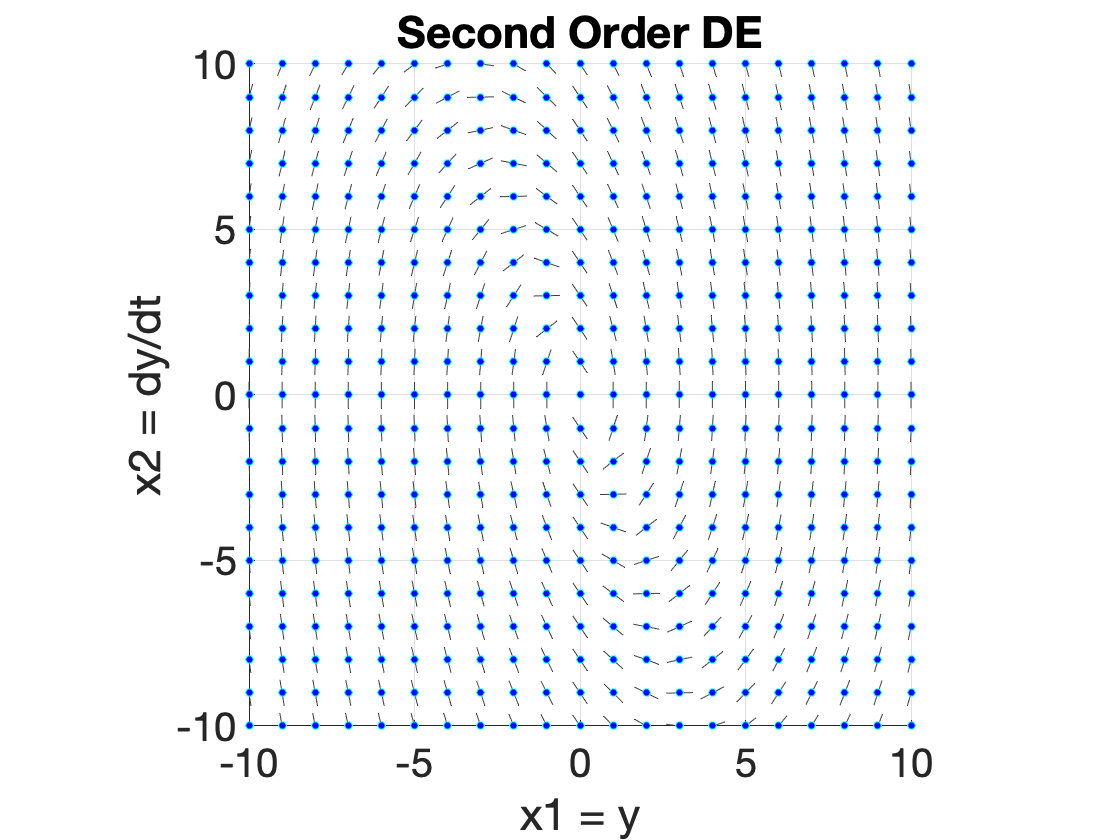


% BLOCK 2: Set the plot window dimensions here.
% Customize the plot settings.
L = 10; % max window dimension
x1min = -L; x1max= L; x2min = -L; x2max = L;
fig = figure(1); % Pop up a new figure
axis([x1min x1max x2min x2max ])
axis square
grid on; hold on
set(gca, 'FontSize', 20)
title('Second Order DE')
xlabel('x1 = y'); ylabel('x2 = dy/dt')

% BLOCK 3 - The Direction Field
radius = 0.4; % Control the size of the tick marks
spacing_horizontal = 1; % Control their horizontal spacing.
spacing_vertical = 1; % Control their vertical spacing.
my_color = [0.25, 0.25, 0.25]; % Control their color.
optional_dots = 1; % Control whether a dot is placed. Use 0 or 1
time = 0;
for x1p = x1min: spacing_horizontal: x1max
    for x2p = x2min: spacing_vertical: x2max
        x=[x1p;x2p]; % Update the state vector x.
        dx = F(time,x) ; % Find dx/dt
        % Add a line here to replace dx by a unit vector. Use norm().
        dx = dx/norm(dx);
        
        dx1 = dx(1) *radius; dx2 = dx(2)*radius; % Scale tick marks.
        % Plot the tick marks!
        plot([x1p - dx1 , x1p + dx1 ], [x2p - dx2 , x2p + dx2] , 'Color', my_color);
        
        if optional_dots
            plot( x1p, x2p, 'cyano', 'MarkerSize', 4, 'MarkerFaceColor', 'blue')
        end
    end
    pause(0.1)
end

% Plot a single solution moving forward in time from the given initial point.
tStart = 0; tEnd = 15;
both_directions = 1; % Change to 0 to draw in the forward direction only.
show_initial_point = 1; % Change to 0 to suppress drawing the initial points.
% Plot the solution curve with the given initial point.
x0 = [4;-3]; % Initial point #1
[~, x_out] = ode45(F, [tStart, tEnd], x0);
plot(x_out(:,1), x_out(:,2), 'red', 'LineWidth', 3)
[~, x_out] = ode45(F, tStart: -0.05: -tEnd, x0); % Backwards!!!
plot(x_out(:,1), x_out(:,2), 'red', 'LineWidth', 3)
% Show initial point using a yellow dot.
if show_initial_point
    plot(x0(1), x0(2), 'bo', 'MarkerSize', 12, 'MarkerFaceColor', 'yellow')
end

% Questions 4-5
deep_purple = [0.5;0;0.5];
x0 = [8;-6]; % Initial point #1
[~, x_out] = ode45(F, [tStart, tEnd], x0);
plot(x_out(:,1), x_out(:,2), 'Color',deep_purple, 'LineWidth', 3)
[~, x_out] = ode45(F, tStart: -0.05: -tEnd, x0); % Backwards!!!
plot(x_out(:,1), x_out(:,2), 'Color',deep_purple, 'LineWidth', 3)
% Show initial point using a yellow dot.
if show_initial_point
    plot(x0(1), x0(2), 'bo', 'MarkerSize', 12, 'MarkerFaceColor', 'yellow')
end

% Question 6
orange = [1, 0.5, 0];
plot([-10,10],[0,0], 'm--', 'LineWidth', 4)
plot([-10,10], [730/24,-730/24], '--', 'Color',orange, 'LineWidth',4)


%% Question 7: Exact solution:
clear, clc, close all
syms y(t) n
D1 = diff(y, t); D2 = diff(y,t,t);

DE = 16*D2 + 24*D1 + 73*y == 0;
sol = dsolve(DE, y(0)==4, D1(0)==-3)

$$sol = 4\,\cos\left(2\,t\right)\,{\mathrm{e}}^{-\frac{3\,t}{4}}$$

## Question 8

clc, clear, close all
% Custom Direction Field for second-order differential equation:
% ay'' + by' + cy = 0

% BLOCK 1: Convert 2nd-order DE to a system of first order DEs.
% The new system will have the form dx/dt = F(t, x) where x is the state
% vector. So, x = [x1; x2]
syms x(t)
% Define the constants here.
a=1; b=-1; c=1;
% Define F(t, x) as an anonymous function.
% Below, x is a column vector with two components
F = @(t, x) [x(2); -(c/a) .* x(1) - (b/a) .* (1- (x(1).^2)/4 ) .* x(2)] 

F = function_handle with value:
    @(t,x)[x(2);-(c/a).*x(1)-(b/a).*(1-(x(1).^2)/4).*x(2)]



% BLOCK 2: Set the plot window dimensions here.
% Customize the plot settings.
L = 10; % max window dimension
x1min = -L; x1max= L; x2min = -L; x2max = L;
fig = figure(1); % Pop up a new figure
axis([x1min x1max x2min x2max ])
axis square
grid on; hold on
set(gca, 'FontSize', 20)
title('Van der Pol Oscillator')
xlabel('x1 = y'); ylabel('x2 = dy/dt')
xticks([x1min:5:x1max])
yticks([x2min:2:x2max])

% BLOCK 3 - The Direction Field
radius = 0.4; % Control the size of the tick marks
spacing_horizontal = 1; % Control their horizontal spacing.
spacing_vertical = 1; % Control their vertical spacing.
my_color = [0.25, 0.25, 0.25]; % Control their color.
optional_dots = 1; % Control whether a dot is placed. Use 0 or 1
time = 0;
for x1p = x1min: spacing_horizontal: x1max
    for x2p = x2min: spacing_vertical: x2max
        x=[x1p;x2p]; % Update the state vector x.
        dx = F(time,x) ; % Find dx/dt
        % Add a line here to replace dx by a unit vector. Use norm().
        dx = dx/norm(dx);
        
        dx1 = dx(1) *radius; dx2 = dx(2)*radius; % Scale tick marks.
        % Plot the tick marks!
        plot([x1p - dx1 , x1p + dx1 ], [x2p - dx2 , x2p + dx2], 'Color', my_color);
        
        if optional_dots
            plot( x1p, x2p, 'cyano', 'MarkerSize', 4, 'MarkerFaceColor', 'blue')
        end
    end
    pause(0.1)
end

% Questions 9-10
% Interactive Graph Session using Mouse clicks
% Use mouse clicks to determine the initial points
% Use ordinary clicks (left clicks)
% Use a right click to end the interactive session or press Enter
clc
fprintf('Starting Interactive Graph Session\n')

Starting Interactive Graph Session


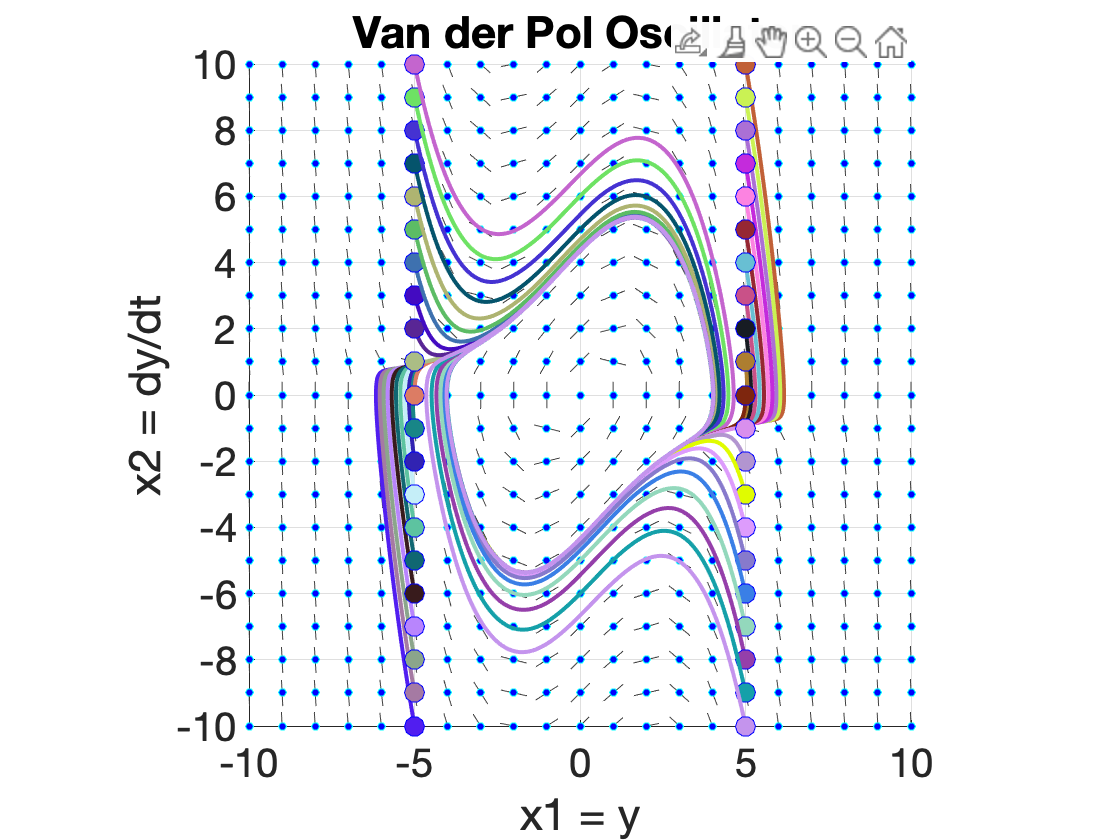

tStart = 0; tEnd = 15;
show_initial_point = 1;
mouse = 1;
while mouse==1
    [x, y, mouse] = ginput(1);
    x0 = [round(x);round(y)]; % Initial point clicked on by user
    [~, x_out] = ode45(F, [tStart :0.01: tEnd], x0); % solution curve using ode45
    my_color = rand(3,1); % a random color
    plot(x_out(:,1), x_out(:,2), 'Color', my_color, 'LineWidth', 2)
    
    % Show initial point using a dot.
    if show_initial_point
        plot(x0(1), x0(2), 'bo', 'MarkerSize', 10, 'MarkerFaceColor', my_color)
    end
end

fprintf('End of Interactive Graph Session\n')

End of Interactive Graph Session
